# Testar Método de Runge-Kutta de Ordem 2

25/04/2021     Paulo Gouveia        a2020121705.isec.pt

25/04/2021     Miguel Ferreira       a2020107016.isec.pt

25/04/2021     Pablo Amaral         a2020143935.isec.pt

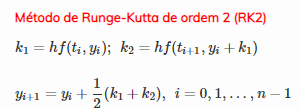

clear
%help function_hnadle

syms y(t)

f =@(t,y) y+exp(3*t)

f = function_handle with value:
    @(t,y)y+exp(3*t)


%f(0,1)
a = 1

a = 1

b = 2

b = 2

n = 20

n = 20

y0 = 2

y0 = 2



yRK2 = NRK2(f,a,b,n,y0)

yRK2 =     2.0000    3.2131    4.6682    6.4067    8.4769   10.9350   13.8467   17.2881   21.3479   26.1295   31.7529   38.3578   46.1067   55.1887   65.8235   78.2667   92.8154  109.8151  129.6673  152.8388  179.8724



sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0)

$$sExata = \frac{{\mathrm{e}}^{3\,t}}{2}+{\mathrm{e}}^{t}\,\left(2\,{\mathrm{e}}^{-1}-\frac{{\mathrm{e}}^{2}}{2}\right)$$

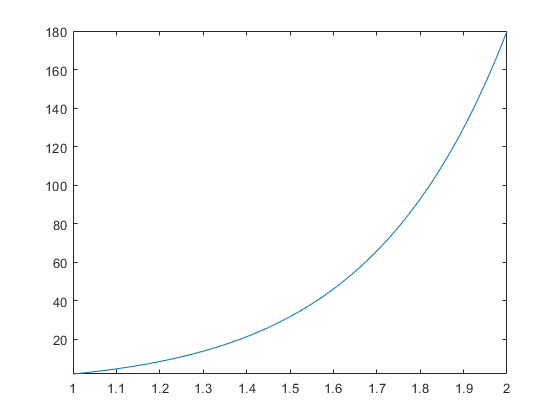

fplot(sExata,[a,b])


g =@(t) eval(vectorize(char(sExata)))

g = function_handle with value:
    @(t)eval(vectorize(char(sExata)))



h = (b-a)/n;
t = a:h:b;
yExata = g(t);
erroRK2 = abs(yExata-yRK2);
tabela = [t.',yExata.',yRK2.',erroRK2.']

tabela =     1.0000    2.0000    2.0000    0.0000
    1.0500    3.2129    3.2131    0.0002
    1.1000    4.6677    4.6682    0.0005
    1.1500    6.4058    6.4067    0.0008
    1.2000    8.4757    8.4769    0.0012
    1.2500   10.9334   10.9350    0.0016
    1.3000   13.8446   13.8467    0.0021
    1.3500   17.2855   17.2881    0.0026
    1.4000   21.3448   21.3479    0.0032
    1.4500   26.1257   26.1295    0.0038


array2table(tabela,"VariableNames",{'t','Exata','RK2','erroRK2'})

ans = 21×4 table
     t      Exata      RK2       erroRK2  
    ____    ______    ______    __________

       1         2         2    1.7764e-15
    1.05    3.2129    3.2131    0.00024469
     1.1    4.6677    4.6682    0.00052275
    1.15    6.4058    6.4067    0.00083832
     1.2    8.4757    8.4769     0.0011961
    1.25    10.933    10.935     0.0016013
     1.3    13.845    13.847       0.00206
    1.35    17.285    17.288     0.0025791
     1.4    21.345    21.348     0.0031665
    1.45    26.126    26.129     0.0038309
     1.5    31.748    31.753     0.0045827
    1.55    38.352    38.358     0.0054335
     1.6      46.1    46.107     0.0063966
    1.65    55.181    55.189     0.0074874
     1.7    65.815    65.824     0.0087234
    1.75    78.257    78.267      0.010125


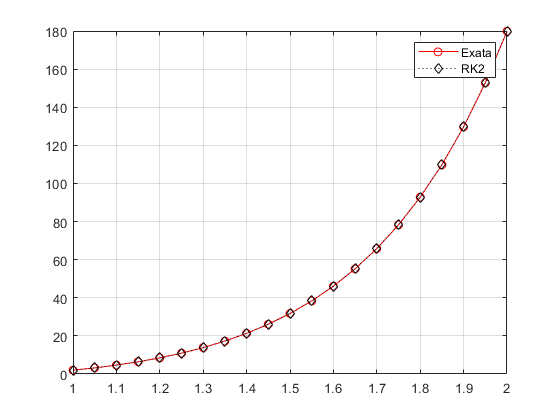


plot(t,yExata,"-ro")
hold on
plot(t,yRK2,"kd:")
hold off
grid on
legend('Exata','RK2')


%whos

 
